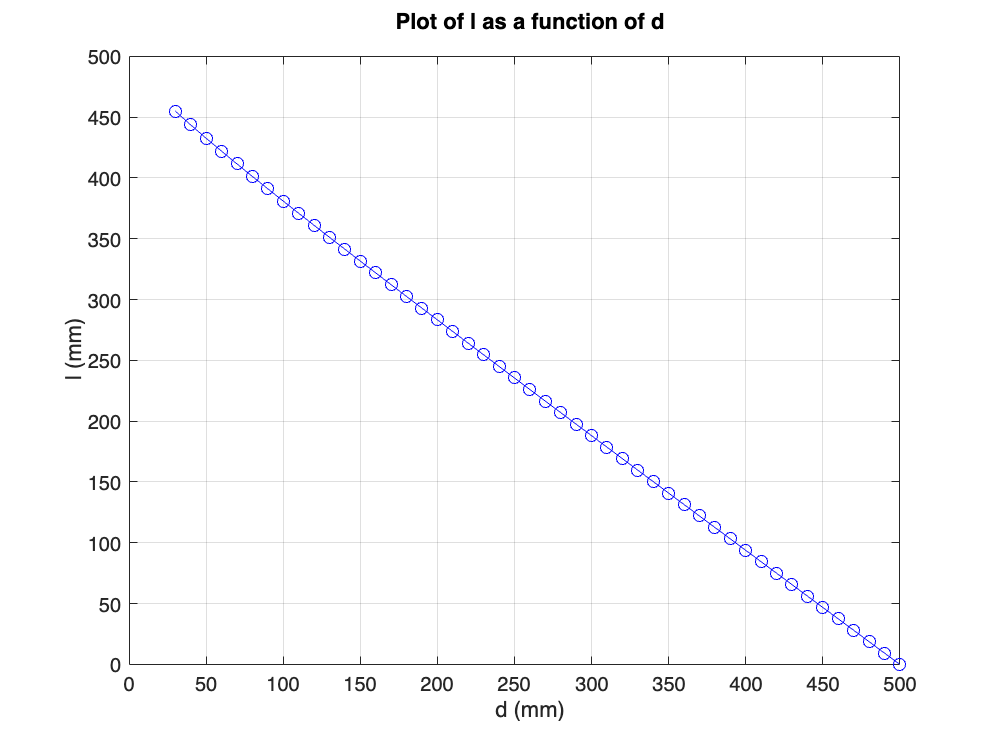

clc; clear; close all;

% Given parameters
a = 200; % mm
d_vals = 30:10:500; % mm
d_min = 30; % mm
d_max = 500; % mm

alpha = 15*3.14/180;
x = 500;

% Precompute fixed constraints
alpha_max1 = asin((x/2) / ((a/2) + d_max));
alpha_max2 = asin((a/2) / ((a/2) + d_min));
%alpha = double(min(alpha_max1, alpha_max2) * 0.95); % Choose slightly smaller alpha


% Initial guess for x within valid range
%x_min_guess = 2 * (a + d_min);
%x = (x_min_guess + x_max) / 2;

% Compute y2 directly without iteration
beta = acos((x/2) / (a/2 + d_max/2));
y2 = ((x/2) * tan(beta)) + d_max/2;

% Precompute sin and cos of alpha for efficiency
sin_alpha = sin(alpha);
cos_alpha = cos(alpha);

% Initialize l_vals and set the first l value to a reasonable guess
l_vals = zeros(size(d_vals));
l_prev = 575; % Initial previous l value

for i = 1:length(d_vals)
    d = d_vals(i);
    syms l
    eq_l = l == (1/cos_alpha) * (y2 - d/2 - sin(acos((x - 2*l*sin_alpha) / (a + d))) * (a/2 + d/2));
    sol_l = double(vpasolve(eq_l, l));

    if isempty(sol_l)
        l_vals(i) = NaN; % Assign NaN if no solution is found
    elseif numel(sol_l) > 1
        % Choose the solution closest to the previous l value
        [~, idx] = min(abs(sol_l - l_prev));
        l_vals(i) = sol_l(idx);
    else
        l_vals(i) = sol_l; % Assign the single solution
    end
    
    % Update the previous l value
    l_prev = l_vals(i);
end

% Plot l as a function of d
figure;
plot(d_vals, l_vals, 'b-o');
xlabel('d (mm)');
ylabel('l (mm)');
title('Plot of l as a function of d');
grid on;


% Display results for d = 500
disp('Results for d = 500 mm:');

Results for d = 500 mm:


disp(['y2: ', num2str(y2)]);

y2: 494.949


disp(['alpha: ', num2str(alpha)]);

alpha: 0.26167


disp(['x: ', num2str(x)]);

x: 500
